1.6a

bb = 1/3*ones(1,3);
xx = [ones(1,10),zeros(1,5)];
yy = firfilt(bb, xx);

1.6b

nn = 1:length(xx);
subplot(2, 1, 1);
stem(nn, xx(nn));
subplot(2, 1, 2);
stem(nn, yy(nn), 'filled')
xlabel('Time Index (n)')

c

Because the 3-point averager utilizes points from the present and past 2 points of the current point, either the current point or some of the previous points may be at zero.

2.1c

2pi(-12)/15 = -1.6pi

-1.6pi + 2pi = 0.4pi

(0.4pi * 15)/2pi = 3 Hz

2.1d

[-2.4pi, -0.4pi, 0.4pi, 2.4pi]

General formula:

locations of digital frequencies = 0.4pi +- 2pi*k where k is a positive integer

2.1e

Because the sampling frequency matches the input frequency, every time the input is sampled, the value will be the same throughout the entire vector (the input +- the period will have the same value). The output would then be constant leading to a frequency of 0.

2.2c

Generally in the given input and impulse response, applying the formula for convolution leads to the current input minus its negative counterpart as a result of the previous input. Because this is dependent on the current and past one input, the non-zero values come from x[0] and the end of the input signal because either the current or past one input is zero.

2.3

load labdat.mat
whos

2.4a

bb = 1/5*ones(1,5);
y1 = firfilt(bb, x1);

Input and output signals' lengths are 100 and 104 respectively.

2.4b

nn = 1:100;
subplot(2,1,1);
stem(nn,x1(nn))
subplot(2,1,2);
stem(nn,y1(nn),'filled') %--Make black dots
xlabel('Time Index (n)')

2.4c

nn = 1:100;
subplot(2,1,1);
stem(nn(34:65),x1(34:65))
subplot(2,1,2);
stem(nn(34:65),y1(34:65),'filled') %--Make black dots
xlabel('Time Index (n)')

2.4d

Because the 5-point averager involves getting the average between the current and past 4 inputs, the result will be the filter's output having less drastic jumps in values, leading to the "smoothing" filter.

2.5a

load echart.mat;
bdiffh = [1, -1];
yy1 = conv2(echart, bdiffh);

imshow(echart);
figure
imshow(yy1);

The dominant color of the input picture is white while the filter output's is black. The letters in the filter output seems to pop out to the left.

2.5b

clear
load echart.mat;
bdiffh = [1, -1];
yy1 = conv2(echart, bdiffh');

imshow(echart);
figure
imshow(yy1);

The dominant color of the input picture is white while the filter output's is black. The letters in the filter output seems to pop out to the top.

3.1a

xx = 256*(rem(0:100,50)<10);
bb = [1 -0.9];
tt = 0:75;

ww = conv(xx, bb);

subplot(2,1,1)
stem(tt, xx(tt+1))
subplot(2,1,2)
stem(tt, ww(tt+1))

The output appears like that because the value of the current output is equal to the value of the current input minus 90% of the previous input. Because most of the input signal is equal to the value of the previous input, the output will have values close to 0. The exceptions are when there are big jumps in input signals (like at x = 50 and x = 10) where the previous value is very different from the current input signal.

b. 

Length of filtered signal = 102

Length of filtered signal = length of input signal + length of filter - 1

                                       = 101 + 2 - 1

                                       = 102

The length of the filtered signal is such because on top of the original signal, the filter works when there is at least one value that is non-zero when applying the filter coefficients. The last happens during "length of input signal + length of filter - 1" because that is when the effect of the last filter coefficient is the last of the input signal while the earlier coefficients' effects are already at 0, since there are no more input signal values to base off of. 

3.1.1a

bb = 0.9.^(0:22);
yy = conv(ww, bb);
tt = 0:75;

3.1.1b

subplot(2,1,1)
stem(tt, ww(tt+1))
subplot(2,1,2)
stem(tt, yy(tt+1))
title('3.1.1b')

3.1.1c

tt = 0:50;
error = abs(yy(tt+1) - xx(tt+1));

stem(tt, error)
title('3.1.1c')

3.1.2a

maxDiff = max(error)

b.

The quality of the restoration should be acceptable, since more of the values error plot are at 0. The worst-case scenario also seems to be acceptable, since compared to the maximum value of the input signal (256), the worst case error (22.6891) is only around 9% of that. Assuming that the scale of the error plot is equal to that of the signals, I would say that the worst case scenario should only be 5% of the scale for it not to be seen.

3.1.3

a. P/8000 = 0.2s

    P = 1600s

    r = 0.9

b. The filter coefficients 'h' are h[0] = 1 and h[1600] = 0.9 where the coefficients between those indices are 0's. The length is 1600 - 0 + 1 = 1601.

c.

load labdat.mat
bb = [1 zeros(1, 1599) 0.9];
yy = conv(x2, bb);

soundsc(yy, 8000)

3.2.1

a

aa = [1 -0.9];
bb = 0.9.^(0:22);
tt = 1:25000;
soundsc(x2, 8000)
yy = conv(aa, x2);
zz = firfilt(bb, yy);

plot(tt(1:length(zz)), zz)

b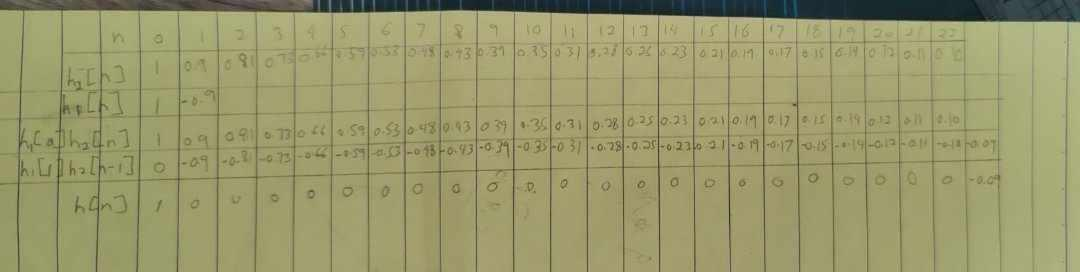    

c. For perfect convolution to be achieved, the condition must be that the convolution of the impulse responses of the cascading system will be equal to the Kronecker delta function where the value at n=0 is 1 and 0 otherwise. This is because when applying this through convolution to the input signal, the result will simply be the input signal.

3.2.2

a

load echart.mat

b

aa = [1 -0.9];
imshow(echart) 
ech90 = conv2(echart, aa); 
ech90 = conv2(ech90, aa');

c

bb = 0.9.^(0:22);
ech90 = conv2(ech90, bb);
ech90 = conv2(ech90, bb');

imshow(ech90)


%combined distorting and restoring
cc = [1 zeros(1, 21) -0.09];
test = conv2(echart, cc);
horizontalTest = test;
imshow(test)
test = conv2(test, cc');
imshow(test) 



    After deconvolving the ech90, the result is for the most part a very similar image to the original echart image. However, the resulting image goes past the original margins of the echart image because of the filter coefficients taking effect on the 0 values outside of the original range of the echart image. What is seen past the original borders is mostly black, but echoes can be observed from the last column of letters in white. The black can be observed as a result of the convolved filter coefficients of the two systems.

    When convolving the filter coefficients of the two systems, the result is the first coefficient being 1 and the last being -0.09 with 21 zeros in between. This resulting vector is essentially the combined effects of the distorting and deconvolving. When applying horizontal filtering first using the aforementioned cascaded coefficients, the excess is all black where the value are either sizeable negative values (getting a portion of the 255 white value then making it negative) or zeros (0/black from the letters not affected by the coefficient yet still black). When applying vertical horizontal filtering, 9% of the previous negative values when multiplied to the coefficient -0.09 becomes positive before being added to the negative value still leads to a black color due to the effects of the addition not being large enough. However, when those values are added to the zeros in the excess, despite being small, it is enough to bring the zeros to positive values, leading to the white echoes that can be observed in the deconvolved pictures.

Magnitude of ghosts = 0.09 * 255 * 0.09 = 2.0655

These ghosts are generally located here (along the horizontal axis):

(Location of 0 values from letters in echart + length of filter coefficients) where the previous is greater than the horizontal length of echart.

%worst-case error
worstError = max(abs(ech90(1:257, 1:256) - echart),[], "all")

worst case error = 45.2010

3.2.3

a

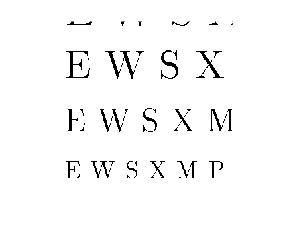

load echart.mat
aa = [1 -0.9];
imshow(echart) 

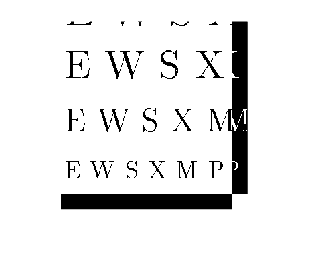

ech90 = conv2(echart, aa); 
ech90 = conv2(ech90, aa');

%M = 22
bb = 0.9.^(0:22);
m22 = conv2(ech90, bb);
m22 = conv2(m22, bb');
imshow(m22)

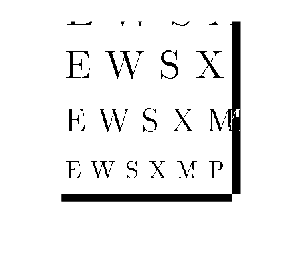


%M = 11
bb = 0.9.^(0:11);
m11 = conv2(ech90, bb);
m11 = conv2(m11, bb');
imshow(m11)

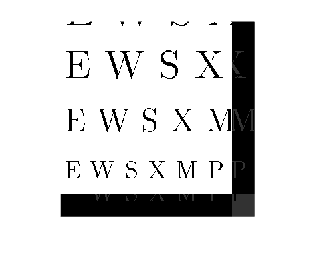


%M = 33
bb = 0.9.^(0:33);
m33 = conv2(ech90, bb);
m33 = conv2(m33, bb');
imshow(m33)

The best result is when M = 33 because the ghosts are not as visible, leaving less distraction from the main deconvolved output image. When M = 22 or 11, on top of the ghosts being more visible, some of the letters have white spots making it not as accurate as when M = 33. The ghosts are gray this time because when M = 33, the negative last coefficient from the convolving of the 2 systems' respective filter coefficients is very small as shown in the convolution below.

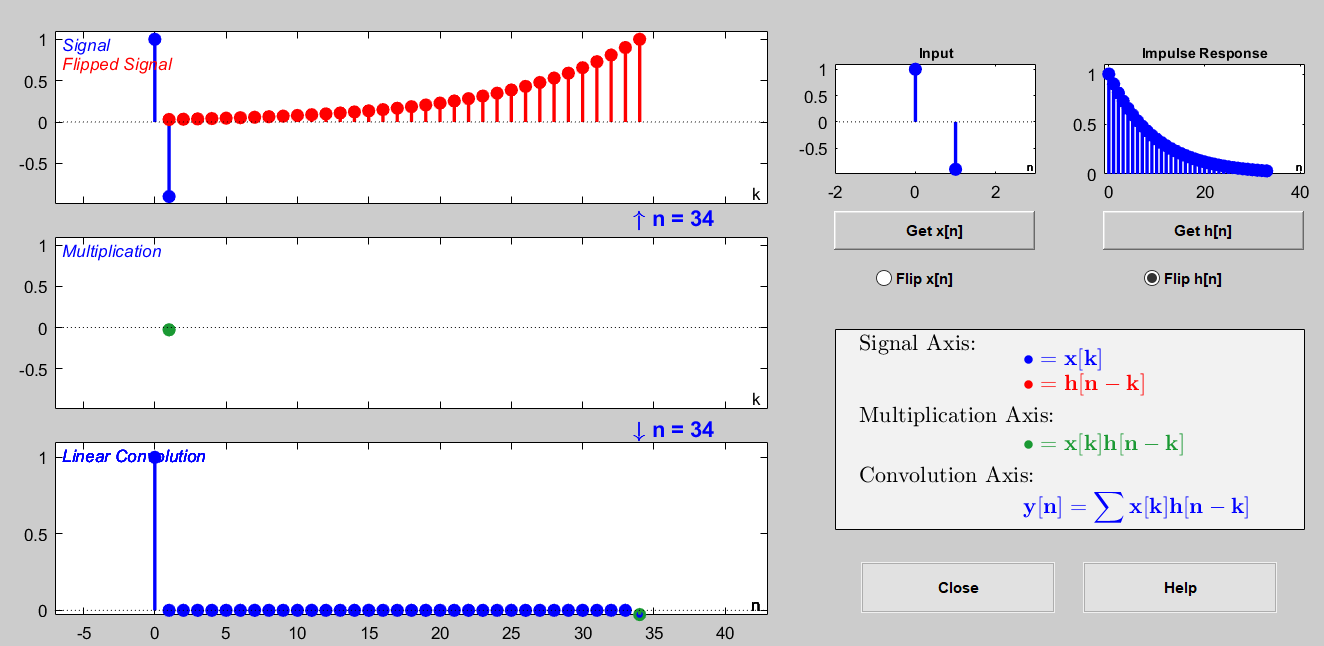

 Among the three M values tested, the main part of the image for the output will have its impulse response closest to the unit impulse sequence. The reasoning behind the black and presence of ghosts is the same as in 3.2.2c. However, the nature of imshow is that when the value is between 0 and 1, what is displayed is gray, leading to a less drastic jump in color from black compared to the ghosts for other M values. 

b

%worst-case error for when M = 33
worst1 = max(abs(m33(1:257, 1:256) - echart),[], "all")

worst1 = 14.1845


%worst-case error for when M = 22
worst2 = max(abs(m22(1:257, 1:256) - echart),[], "all")

worst2 = 45.2010


%worst-case error for when M = 11
worst3 = max(abs(m11(1:257, 1:256) - echart),[], "all")

worst3 = 144.0391

  worst-case errors for each M value:

when M = 33: 14.1845

when M = 22: 45.2010

when M = 11: 144.0391

 With how little the change in level is, I believe it would be hard to notice it straight away unless one were to carefully examine the change for a while.